# Everage ERP Analysis

This code takes the epoches from each class (sick & non sick) and get a single averaged epoch per class. The averaging is performed seperately for each extraction method (i.e Activation Maximization & Sorting)

# Activation Maximization

clear;
load('C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_roi\trial 4\maximization\matrix_jitter_output.mat');
participant_no = 29; % Number of participants
srate = 250;

summed_sick = int32(zeros(16,250));
summed_normal = int32(zeros(16,250));

for i = (1:participant_no)
    fieldName = ['field', num2str(i)];

    % Get the sick and normal samples
    sick_sample = export_matlab.(fieldName).sick;
    normal_sample = export_matlab.(fieldName).normal;

    summed_sick = summed_sick + sick_sample;
    summed_normal = summed_normal + normal_sample;
end

averaged_ERP_sick = summed_sick / participant_no;
averaged_ERP_normal = summed_normal / participant_no;

## Plot Average ERP

figure; % create a new figure
samples = (1:srate);
time = (samples*1000)/srate;
% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 2 columns, and select the first plot
for i = 1:size(averaged_ERP_sick, 1) % loop over rows
    plot(time, averaged_ERP_sick(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Averaged Sick ERP');
ylabel('Volatage Amplitude (uV)');
xlabel('Sample Number');
% ylim([0, 0.15]);

% Plot for matrix B
subplot(1,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(averaged_ERP_normal, 1) % loop over rows
    plot(time, averaged_ERP_normal(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Averaged Sick ERP');
ylabel('Volatage Amplitude (uV)');
xlabel('Sample Number');
% ylim([0, 0.15]);

# Sorting

clear;
load('C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_roi\trial6\sorting\matrix_jitter_output.mat');
srate = 250;
sample_no = 29;
line_thickness = 1;

% BEST SAMPLE VARIABLES 
t_s_summed = zeros(16, srate); % The sum of the channel across subjects (16 X 250) => (Channels X Samples)
t_n_summed = zeros(16, srate); % The sum of the channel across subjects (16 X 250) => (Channels X Samples)

% WORST SAMPLE VARIABLES
f_s_summed = zeros(16, srate); % The sum of the channel across subjects (16 X 250) => (Channels X Samples)
f_n_summed = zeros(16, srate); % The sum of the channel across subjects (16 X 250) => (Channels X Samples)

f_channels = [4, 5, 6, 7, 8] - 3; % Frontal channels
c_channels = [9, 10, 11, 12, 13] - 3; % Central channels
p_channels =  [14, 15, 16] - 3; % Parietal channels
o_channels = [17, 18, 19] - 3; % Occipital channels
r_channels = [9, 10, 13, 14, 15, 16, 17, 18] - 3; % ROI Channels

c_regions = {f_channels, c_channels, p_channels, o_channels, r_channels};

for i = (1:sample_no)
    fieldName = ['field', num2str(i)];

    % GET THE SAMPLES
    % Get the best sick and normal samples
    true_sick_sample = export_matlab.(fieldName).true_sick;
    true_normal_sample = export_matlab.(fieldName).true_normal;

    % Get the worst sick and normal samples
    false_sick_sample = export_matlab.(fieldName).false_sick;
    false_normal_sample = export_matlab.(fieldName).false_normal;

    % GET THE SPECTRAS
    % Get the best spectra and their respective frequncies for both classes
    if ~isempty(true_sick_sample)
        t_s_summed = t_s_summed + mean(true_sick_sample, 3);
    end
    if ~isempty(true_normal_sample)
        t_n_summed = t_n_summed + mean(true_normal_sample, 3);
    end

    % Get the worst spectra and their respective frequncies for both classes
    if ~isempty(false_sick_sample)
       f_s_summed = f_s_summed + mean(false_sick_sample, 3);     
    end
    if ~isempty(false_normal_sample)
        f_n_summed = f_n_summed + mean(false_normal_sample, 3);
    end

end


% GET THE AVERAGED ERP
averaged_ERP_t_s = t_s_summed / sample_no;
averaged_ERP_t_n = t_n_summed / sample_no;
averaged_ERP_f_s = f_s_summed / sample_no;
averaged_ERP_f_n = f_n_summed / sample_no;

% REGIONAL DATA
true_sick_region_array = zeros(length(c_regions), srate);  
true_normal_region_array = zeros(length(c_regions), srate); 
false_sick_region_array = zeros(length(c_regions), srate);  
false_normal_region_array = zeros(length(c_regions), srate);

region_cases = {true_sick_region_array, true_normal_region_array, false_sick_region_array, false_normal_region_array};
channel_cases = {averaged_ERP_t_s, averaged_ERP_t_n, averaged_ERP_f_s, averaged_ERP_f_n};

for case_id = (1:length(region_cases))
    for region_id = (1:length(c_regions))
        c_placeholder = mean(channel_cases{case_id}(c_regions{region_id},:), 1);
        region_cases{case_id}(region_id,:) = c_placeholder;
    end
end

labels = {'Frontal', 'Central', 'Parietal', 'Occipital'};

## Plot Averaged ERP for All Channels

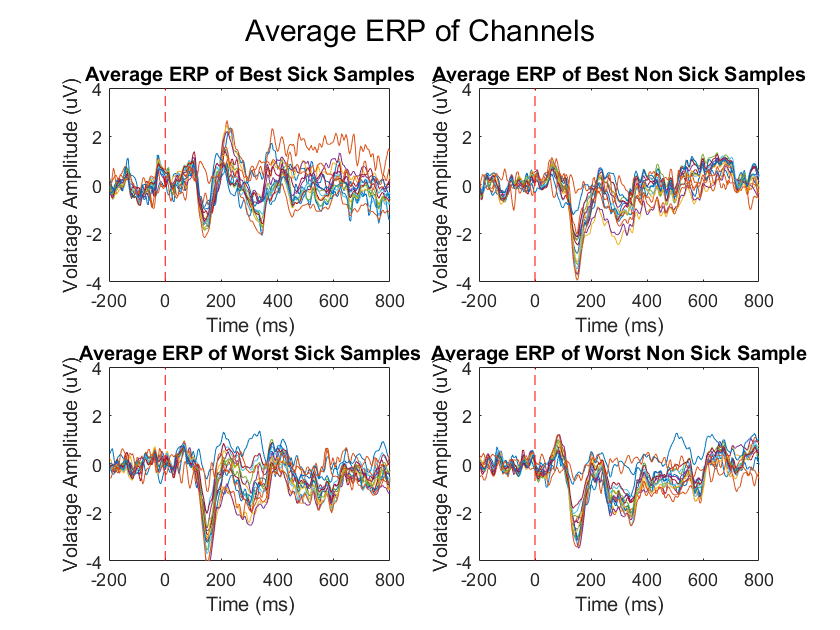

figure; % create a new figure
samples = (1:srate);
time = ((samples*1000)/srate) - 200;
x = 0;
% Plot for matrix Sick
subplot(2,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(averaged_ERP_t_s, 1) % loop over rows
    plot(time,averaged_ERP_t_s(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of Best Sick Samples');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--');
xlim([-200, 800]);
ylim([-4, 4]);

subplot(2,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(averaged_ERP_t_n, 1) % loop over rows
    plot(time,averaged_ERP_t_n(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of Best Non Sick Samples');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--');
xlim([-200, 800]);
ylim([-4, 4]);

subplot(2,2,3); % Divide plot into 2 row, 1 columns, and select the first plot
for i = 1:size(averaged_ERP_f_s, 1) % loop over rows
    plot(time,averaged_ERP_f_s(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of Worst Sick Samples');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--');
xlim([-200, 800]);
ylim([-4, 4]);

subplot(2,2,4); % Divide plot into 2 row, 2 columns, and select the first plot
for i = 1:size(averaged_ERP_f_n, 1) % loop over rows
    plot(time,averaged_ERP_f_n(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of Worst Non Sick Sample');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--');
xlim([-200, 800]);
ylim([-4, 4]);
sgtitle('Average ERP of Channels');

## Average ERP For Regions

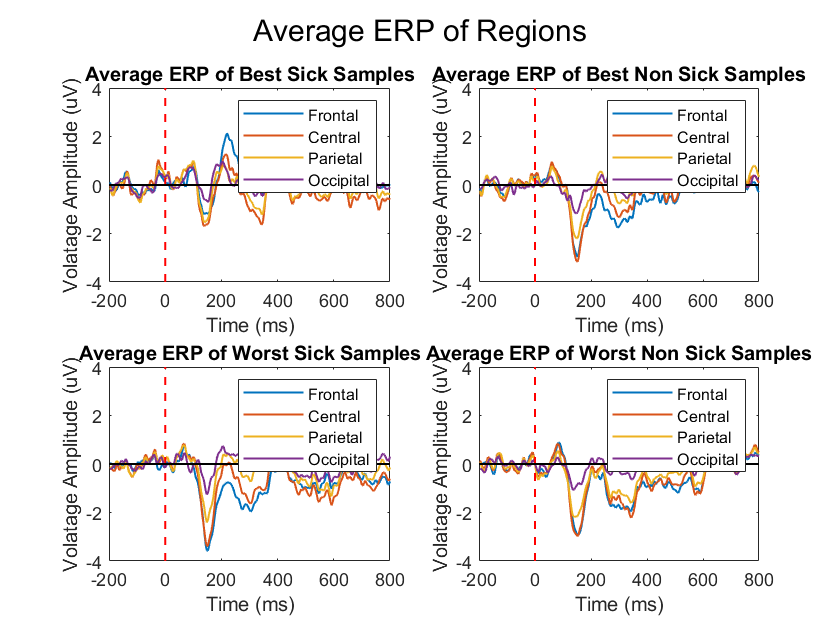

figure; % create a new figure
samples = (1:srate);
time = ((samples*1000)/srate) - 200;
x = 0;
% Plot for matrix Sick
subplot(2,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(region_cases{1}, 1) - 1 % loop over rows
    plot(time,region_cases{1}(i,:),'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of Best Sick Samples');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--', 'LineWidth', line_thickness);
xlim([-200, 800]);
line(xlim, [0 0], 'Color', 'k', 'LineStyle', '-', 'LineWidth', line_thickness);
ylim([-4, 4]);
legend(labels);

subplot(2,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(region_cases{2}, 1) - 1 % loop over rows
    plot(time,region_cases{2}(i,:), 'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of Best Non Sick Samples');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--', 'LineWidth', line_thickness);
xlim([-200, 800]);
line(xlim, [0 0], 'Color', 'k', 'LineStyle', '-', 'LineWidth', line_thickness);
ylim([-4, 4]);
legend(labels);

subplot(2,2,3); % Divide plot into 2 row, 1 columns, and select the first plot
for i = 1:size(region_cases{3}, 1) - 1 % loop over rows
    plot(time,region_cases{3}(i,:), 'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of Worst Sick Samples');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--', 'LineWidth', line_thickness);
xlim([-200, 800]);
line(xlim, [0 0], 'Color', 'k', 'LineStyle', '-', 'LineWidth', line_thickness);
ylim([-4, 4]);
legend(labels);

subplot(2,2,4); % Divide plot into 2 row, 2 columns, and select the first plot
for i = 1:size(region_cases{4}, 1) - 1 % loop over rows
    plot(time,region_cases{4}(i,:), 'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Average ERP of Worst Non Sick Samples');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--', 'LineWidth', line_thickness);
xlim([-200, 800]);
line(xlim, [0 0], 'Color', 'k', 'LineStyle', '-', 'LineWidth', line_thickness);
ylim([-4, 4]);
legend(labels);

sgtitle('Average ERP of Regions');

## Difference Wave of Average ERP

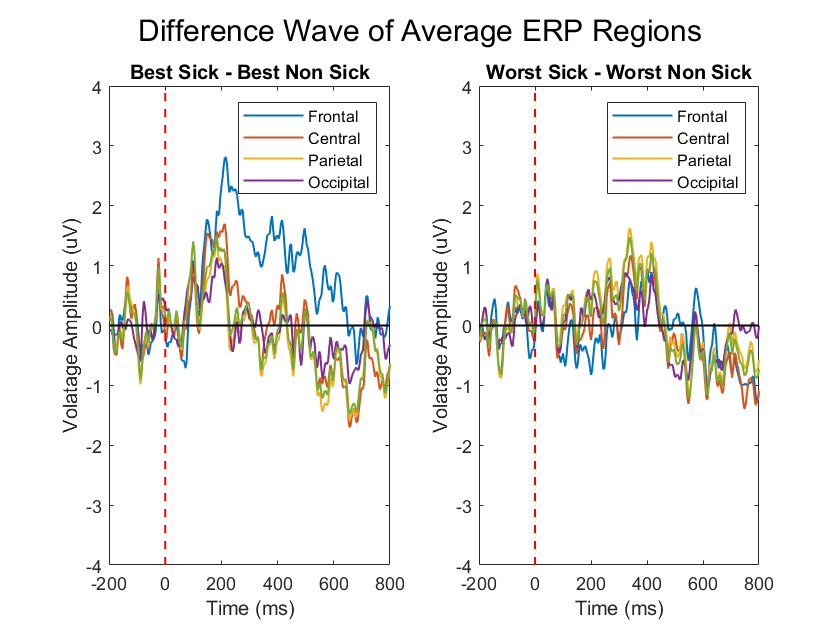

figure; % create a new figure
samples = (1:srate);
time = ((samples*1000)/srate) - 200;
x = 0;
% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(region_cases{1}, 1) % loop over rows
    plot(time,region_cases{1}(i,:) - region_cases{2}(i,:), 'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Best Sick - Best Non Sick');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--', 'LineWidth', line_thickness);
xlim([-200, 800]);
line(xlim, [0 0], 'Color', 'k', 'LineStyle', '-', 'LineWidth', line_thickness);
ylim([-4, 4]);
legend(labels);

subplot(1,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(region_cases{3} , 1) % loop over rows
    plot(time,region_cases{3}(i,:) - region_cases{4}(i,:), 'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('Worst Sick - Worst Non Sick');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--', 'LineWidth', line_thickness);
xlim([-200, 800]);
line(xlim, [0 0], 'Color', 'k', 'LineStyle', '-', 'LineWidth', line_thickness);
ylim([-4, 4]);
legend(labels);

sgtitle('Difference Wave of Average ERP Regions');

## Average ERP of ROI

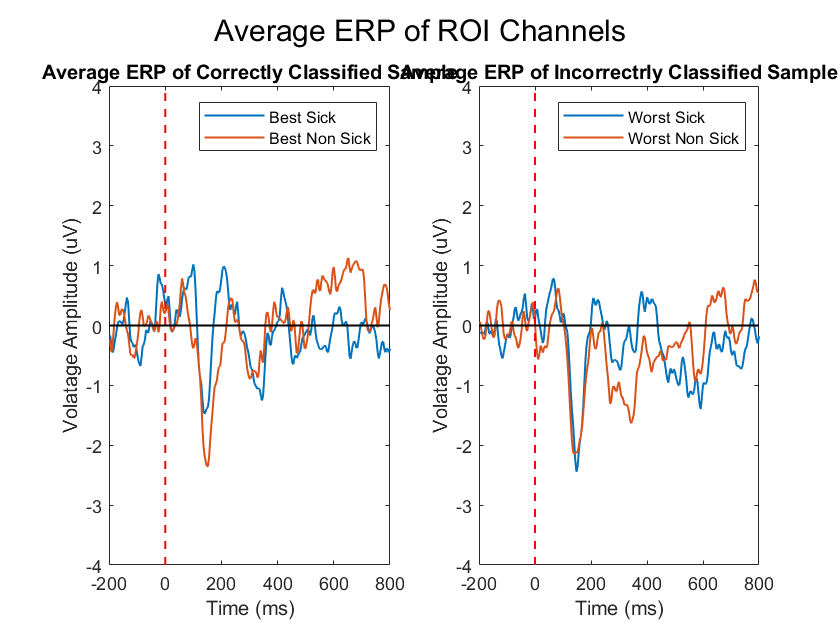

figure; % create a new figure
samples = (1:srate);
time = ((samples*1000)/srate) - 200;
x = 0;
% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 1 columns, and select the first plot

plot(time,region_cases{1}(5,:), 'LineWidth', line_thickness); % plot each row on the same plot
hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
plot(time,region_cases{2}(5,:), 'LineWidth', line_thickness); % plot each row on the same plot
hold on;
title('Average ERP of Correctly Classified Sample');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--', 'LineWidth', line_thickness);
xlim([-200, 800]);
line(xlim, [0 0], 'Color', 'k', 'LineStyle', '-', 'LineWidth', line_thickness);
ylim([-4, 4]);
legend({'Best Sick', 'Best Non Sick'});

subplot(1,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
plot(time,region_cases{3}(5,:), 'LineWidth', line_thickness); % plot each row on the same plot
hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
plot(time,region_cases{4}(5,:), 'LineWidth', line_thickness); % plot each row on the same plot
hold on;
title('Average ERP of Incorrectrly Classified Sample');
ylabel('Volatage Amplitude (uV)');
xlabel('Time (ms)');
line([x x], [-10 10], 'Color', 'red', 'LineStyle', '--', 'LineWidth', line_thickness);
xlim([-200, 800]);
line(xlim, [0 0], 'Color', 'k', 'LineStyle', '-', 'LineWidth', line_thickness);
ylim([-4, 4]);
legend({'Worst Sick', 'Worst Non Sick'});

sgtitle('Average ERP of ROI Channels');